clear all;
clc;


## Signal Generation

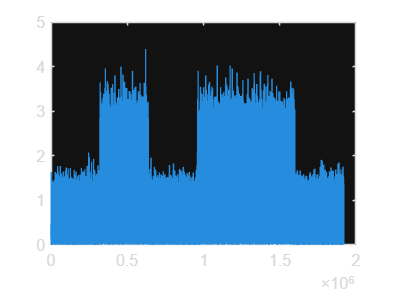

% Constant parameters:
s.N = 1024;
s.Fs = 240e6;
s.Ng = 32;
s.type = "QAM";
s.Nsym = 300;
s.Nsfd = 300;
s.Fc = getClosestFch(11.775e9);
FrameDuration = 1/750;

% Changable parameters:
s.SNRdB = 5.5;
s.Fsr = s.Fs;
s.Midx = 4;
s.beta = 0;
s.Fcr = s.Fc;
s.tau = 0;
NumOfFrames = 6;
s.gutter = 1;
% For Tf Estimation, two of the frames should be neighbors
s.present = [0 , 1 , 0 , 1 , 1 , 0];

% Parameter calculations based on changables:
s.Tdur = NumOfFrames * FrameDuration;
if(s.gutter == 1)
    Nd = s.N - 4;
else
    Nd = s.N;
end
data = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = data;

% Generating the signal:
input = genStrlkStream(s);
t = 1:length(input);
plot(t , abs(input));

% Clearing everything to start blind identification:
clearvars -except input data;

% Filling the known parameters based on the capture:
Fsr = 240e6;
s.Fsr = Fsr;

Fcr = getClosestFch(11.775e9);
s.Fcr = Fcr;

s.data = input;

## Starting The Blind Identification

% Estimating the number of subcarriers(N):
N = N_Est(s)

N = 1024

s.N = N;

% Estimating the signal bandwidth(Fs);
Fs = Fs_Est(s)

Fs = 240000000

s.Fs = Fs;

% Resampling the signal:
newInput = resample(input , Fs , s.Fsr);
s.data = newInput;

% Estimating the cyclic prefix length(Ng):
Ng = Ng_Est(s)

Ng = 32

s.Ng = Ng;

% Estimating the time for one frame(Tf):
Tf = Tf_Est(s)

Tf = 0.0013

s.Tf = Tf;

% Calculating the number of non-zero symbols per frame,
% number of data symbols in a fram and frame guard interval
[Nsf , Nsfd , Tfg] = Nsf_Nsfd_Tfg_Est(s)

Nsf = 302

Nsfd = 298

Tfg = 4.5333e-06

s.Nsf = Nsf;
s.Nsfd = Nsfd;
s.Tfg = Tfg;

% Symbol and carrier frequency synchronization
[beta0 , nm0] = Sym_CF_Est(s)

beta0 = 1.9820e-07

nm0 = 320000

s.beta0 = beta0;
s.nm0 = nm0;

